# Pattern Multiplication and Mutual Coupling

Often arrays are combined with directive antenna elements.  When the elements are highly directive, or when the array elements are placed close together, the mutual coupling between elements can be significant.  In this demo, we show how to:

- Compute un-normalized steering vectors for array with elements using pattern multiplication.  This method is simple, but approximate since it ignores mutual coupling.

- Normalizing the antenna pattern to account for mutual coupling

- Visualizing the normalized antenna pattern

## Creating a Simple Patch Antenna and Array

To illustrate the concept, we use a simple patch microstrip antenna element which are typical at 28 GHz:

fc = 28e9;  % Carrier frequency
elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis = [0,1,0];

We can plot the element pattern.  We see the peak gain is 10.1 dBi.

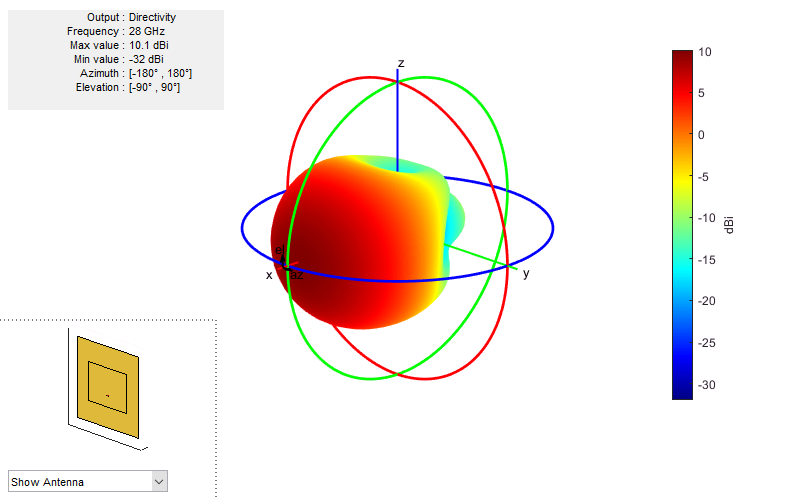

elem.pattern(fc);

For the calculations below, we store the element gain in a matrix where e`lemGain(i,j)` is the directivity (in dB) at `el(i), az(j)`. 

% Get the element pattern
[elemGain,az,el] = elem.pattern(fc,'Type', 'Directivity');   

We will create a gridded interpolant to be able to access the element gain at other values.

% Create the gridded interpolant object.
elemGainInterp = griddedInterpolant({el,az},elemGain);

Next, we construct an 4 x 4 uniform rectangular array:

% Construct a URA
nant = [4,4];
lambda = physconst('Lightspeed') / fc;
dsep = 0.5*lambda;
arr = phased.URA(nant,dsep,'ArrayNormal','x');


We can plot the array pattern without the element gain

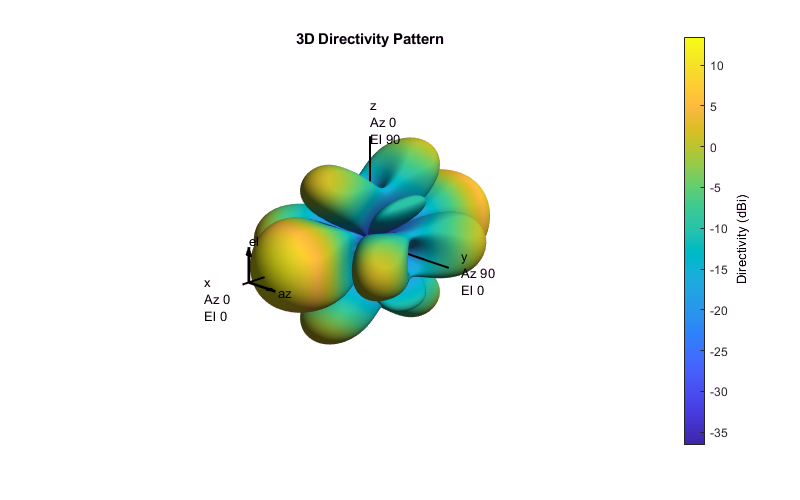

clf;
arr.pattern(fc);

## Compute the Gain with Pattern Multiplication and No Normalization

We first compute the un-normalized steering vectors assuming pattern multiplication without multiplication.  This gain is approximate.   We first get the steering vectors at the same angles that we measured the element gains:

% Get grid of values
[azMat, elMat] = meshgrid(az, el);
azVal = azMat(:);
elVal = elMat(:);
elemGainVal = elemGain(:);

% Create a steering vector object
svObj = phased.SteeringVector('SensorArray', arr);

% Get the steering vectors
Sv = svObj(fc, [azVal elVal]'); 


The un-normalized steering vectors with element gain can then be computed with pattern multiplication.

% Spatial signature with element gain
elemGainLin = db2mag(elemGainVal);
SvNoNorm = Sv.*elemGainLin';

To compute the maximum gain can then be computed as follows:  For a given direction `k, SvNoNorm(:,k) `is the steering vector with element gain.  Beamforming in this direction, we get a gain of  `||SvNoNorm(:,k)||^2.  `

% Compute gain with no normalization
gainNoNorm = pow2db(sum(abs(SvNoNorm).^2, 1));

% Max gain
maxGainNoNorm = max(gainNoNorm);
fprintf('Max Gain = %7.2f', maxGainNoNorm);

Max Gain =   22.13

Finally, we plot the maximum gain

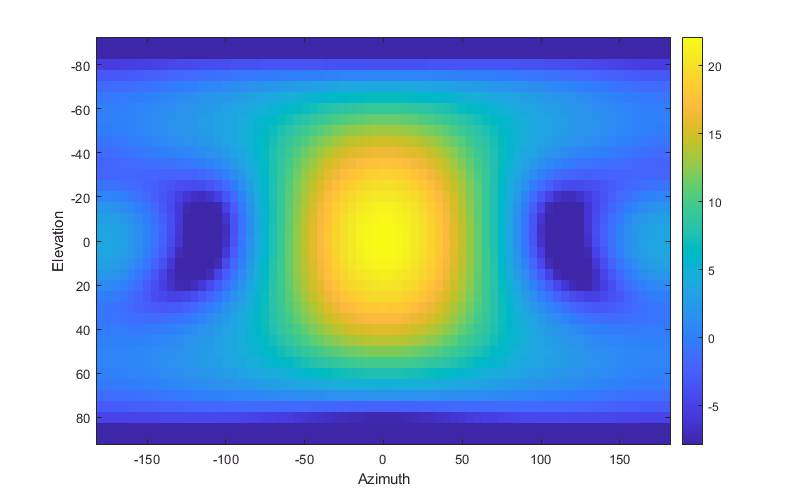

% Reshape to a grid
gainNoNormMat = reshape(gainNoNorm,nel,naz);

% Set the colorlimits 
clim = [maxGainNoNorm-30, maxGainNoNorm];

% Plot the gain
clf;
imagesc(az, el, gainNoNormMat, clim);
colorbar();
xlabel('Azimuth');
ylabel('Elevation');

## Computing the Normalized Steering Vector

To compute the normalized steering vectors, we first compute the scaled resistance matrix.  


% Compute the normalization matrix
nang = length(elVal);
cosel = cos(deg2rad(elVal));
Q = (1/nang)*(SvNoNorm.*cosel')*(SvNoNorm') / mean(cosel);

% Ensure matrix is Hermitian
Q = (Q+Q')/2;

Then, we normalize the steering vectors:

% Compute the adjusted spatial signature matrix
SvNorm = sqrtm(Q)\ SvNoNorm;

Now, we compare the normalized and un-normalized max gains.

% Compute gain with no normalization
gainNorm = pow2db(sum(abs(SvNorm).^2, 1));

% Max gain
maxGainNorm = max(gainNorm);
fprintf('Max Gain no normalization = %7.2f\n', maxGainNoNorm);

Max Gain no normalization =   22.13


fprintf('Max Gain normalization    = %7.2f\n', maxGainNorm);

Max Gain normalization    =   18.35


We plot the two gains to compare.

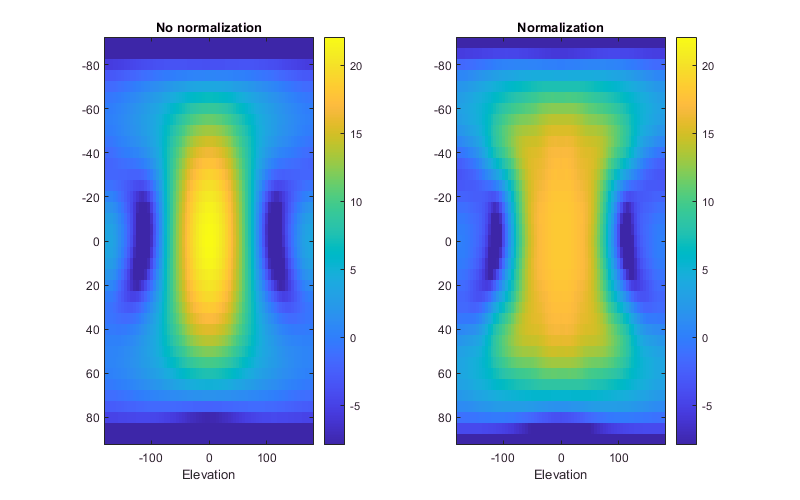

% Reshape to a grid
gainNormMat = reshape(gainNorm,nel,naz);

% Set the colorlimits 
gmax = max(maxGainNoNorm, maxGainNorm);
clim = [gmax-30, gmax];

% Plot the gains
set(gcf,'Position', [0,0,800,500]);
subplot(1,2,1);
imagesc(az, el, gainNoNormMat, clim);
colorbar();
clim = [dmax-30, dmax];
title('No normalization');
xlabel('Azimuth');
xlabel('Elevation');

subplot(1,2,2);
imagesc(az, el, gainNormMat, clim);
colorbar();
title('Normalization');
xlabel('Azimuth');
xlabel('Elevation');

## Plotting the Array Factors

We next show the change in array factors.  We generate BF vectors for two angles.  For each angle, we compute the resulting array factor using pattern multiplication with and without normalization.

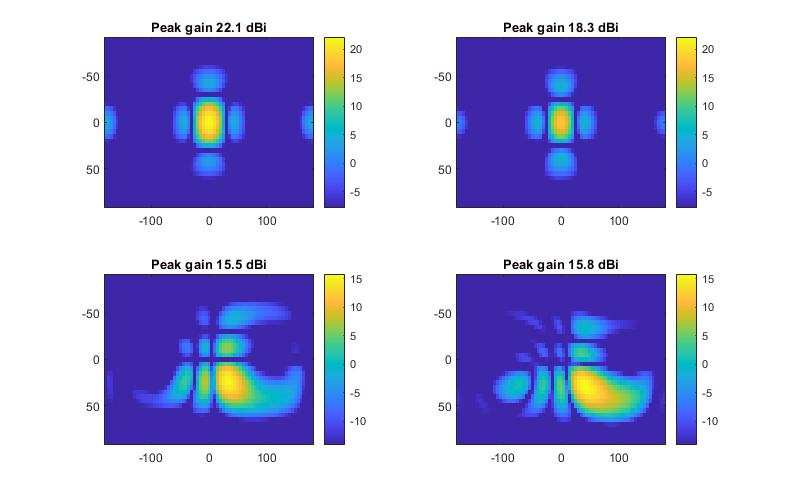

% Angles to get the beamforming vectors
az0 = [0 45]';
el0 = [0 30]';
nw = length(az0);

% Get the steering vectors
svObj.release();
Sv0 = svObj(fc, [az0 el0]'); 

% Get the element gains
elemGain0 = elemGainInterp([el0 az0]);
elemGainLin0 = db2mag(elemGain0);

% Steering vectors with no normalization
SvNoNorm0 = Sv0.*elemGainLin0';

% Steering vectors with normalization
SvNorm0 = sqrtm(Q) \ SvNoNorm0;

clf;
for i = 1:nw

    % Take conjugate BF
    wNoNorm = conj(SvNoNorm0(:,i));
    wNoNorm = wNoNorm / norm(wNoNorm);
        
    % Compute the array pattern on the test angles
    AFNoNorm = mag2db(abs(sum(wNoNorm.*SvNoNorm,1)));
    AFNoNormMat = reshape(AFNoNorm, nel, naz);
    
    % Take conjugate BF with normalization
    wNorm = conj(SvNorm0(:,i));
    wNorm = wNorm / norm(wNorm);    
    
    % Compute the array pattern with normalization
    AFNorm = mag2db(abs(sum(wNorm.*SvNorm,1)));
    AFNormMat = reshape(AFNorm, nel, naz);
    
    % Get the color limits
    gmax = max(max(AFNorm), max(AFNoNorm));    
    clim = [gmax-30, gmax];
    
    % Plot
    subplot(nw,2,2*i-1);
    imagesc(az, el, AFNoNormMat, clim);
    colorbar();
    title(sprintf('Peak gain %3.1f dBi', max(AFNoNorm)));
    
    
    subplot(nw,2,2*i);
    imagesc(az, el, AFNormMat, clim);
    colorbar();
    title(sprintf('Peak gain %3.1f dBi', max(AFNorm)));

end